# Plot the zeroth order Poynting vector in Fourier space of the SFG scattered field for a sweep of parameters

phi = 0[deg], orientation_xy = 45[deg]

study_num = 1

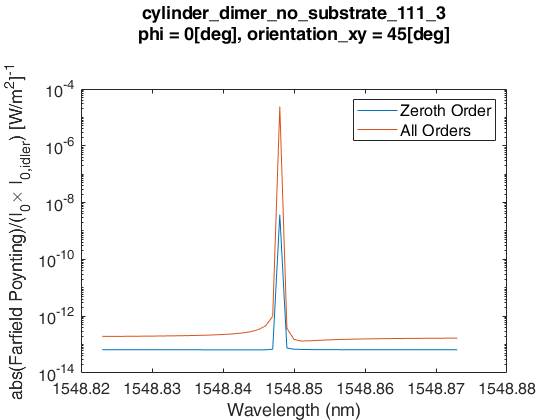

phi = 0[deg], orientation_xy = 90[deg]

study_num = 2

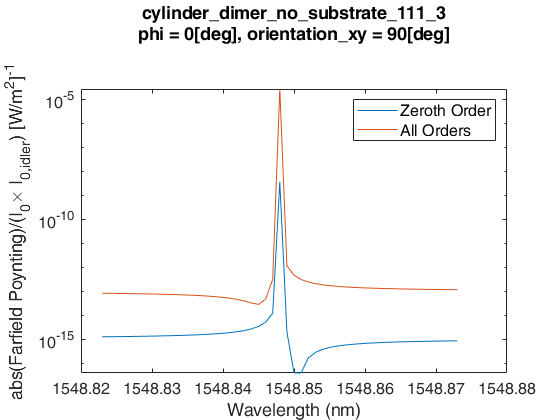

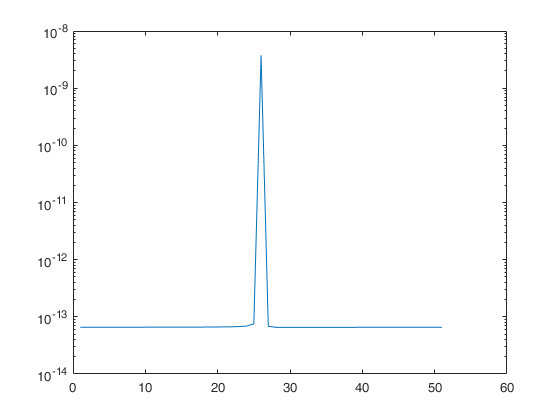

phi = 0[deg], orientation_xy = 0[deg]

study_num = 3

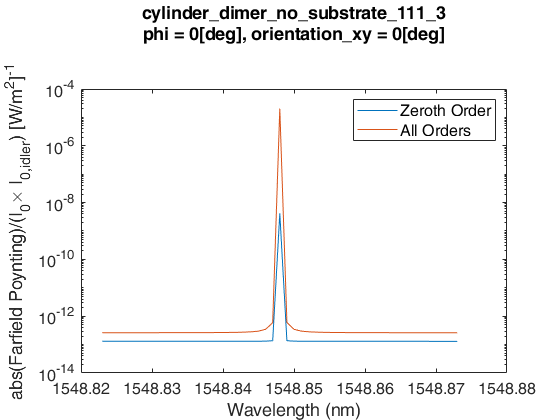

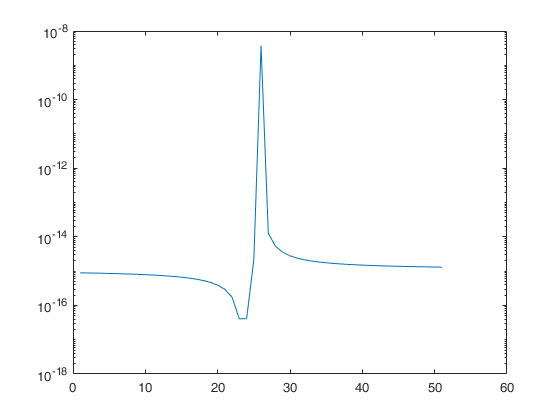

phi = 45[deg], orientation_xy = 45[deg]

study_num = 4

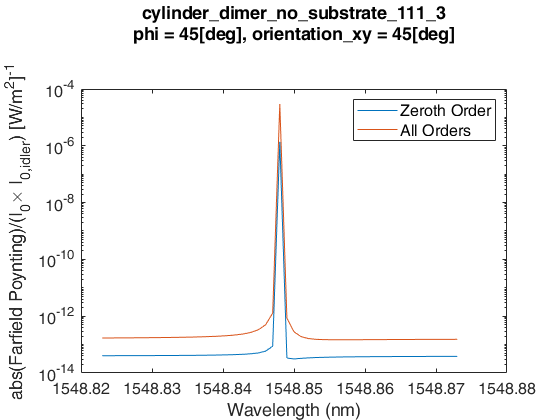

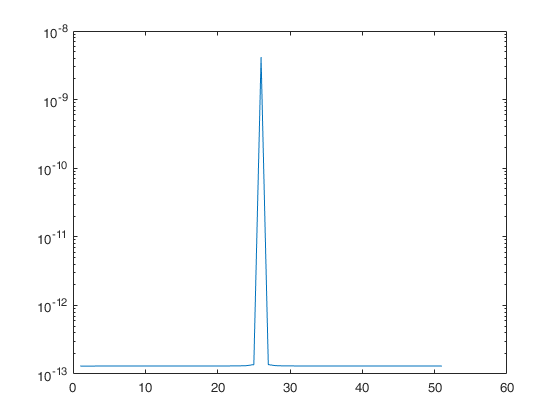

phi = 45[deg], orientation_xy = 90[deg]

study_num = 5

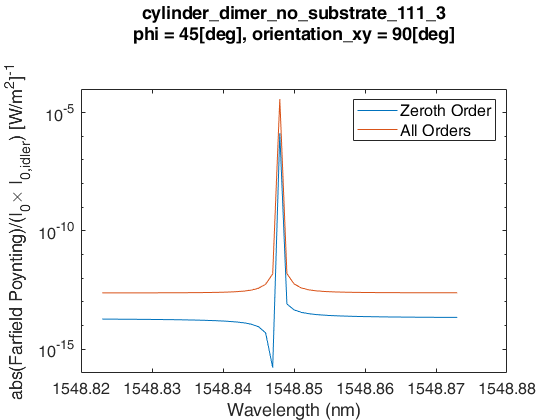

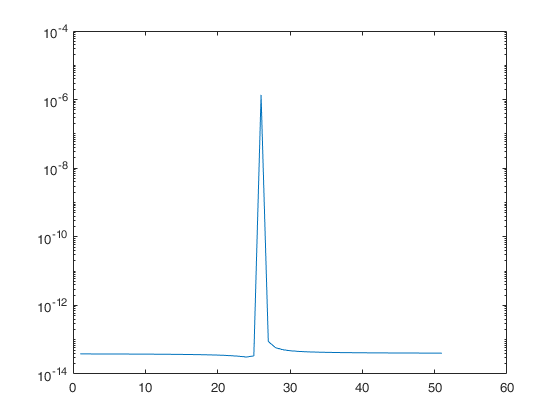

phi = 45[deg], orientation_xy = 0[deg]

study_num = 6

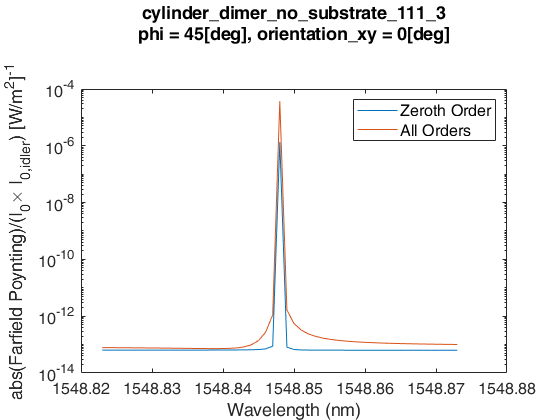

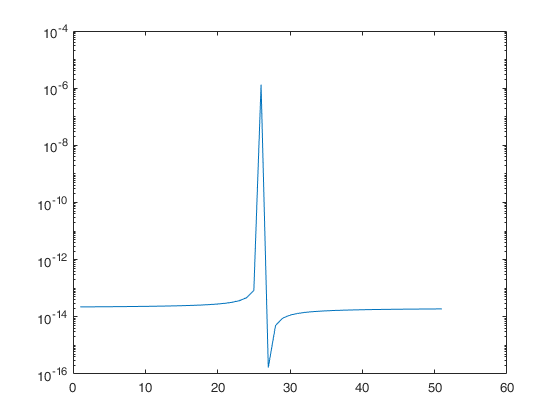

phi = 90[deg], orientation_xy = 45[deg]

study_num = 7

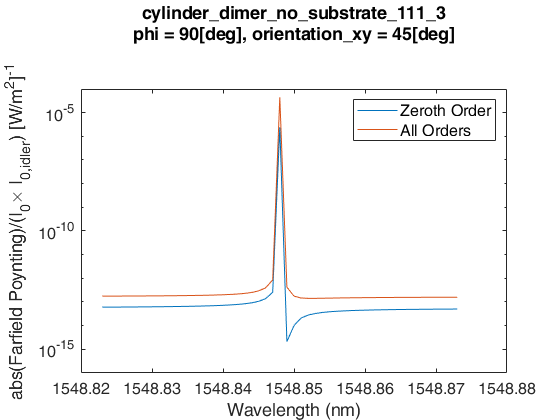

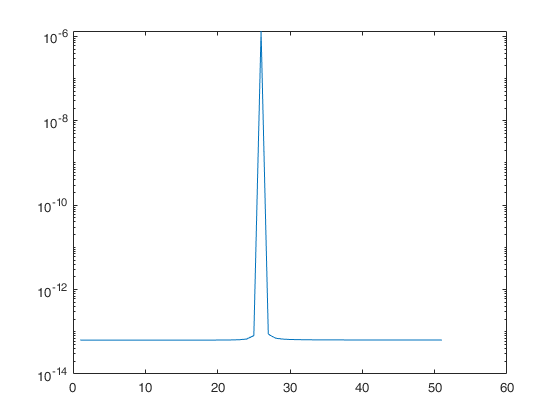

phi = 90[deg], orientation_xy = 90[deg]

study_num = 8

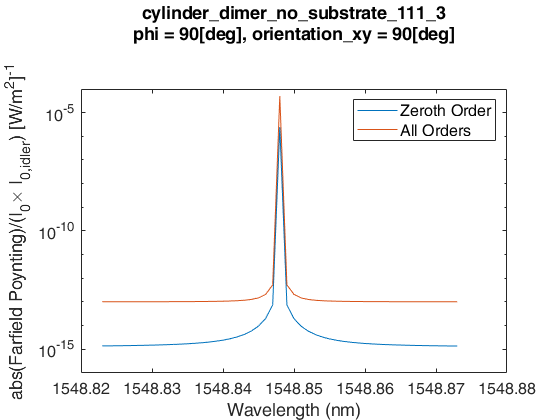

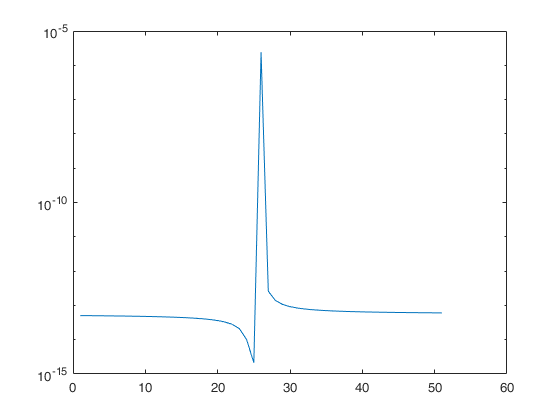

phi = 90[deg], orientation_xy = 0[deg]

study_num = 9

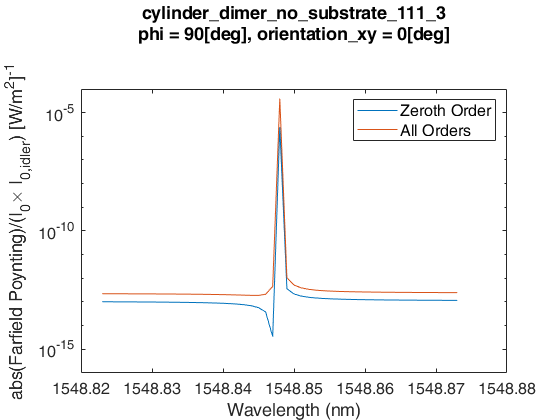

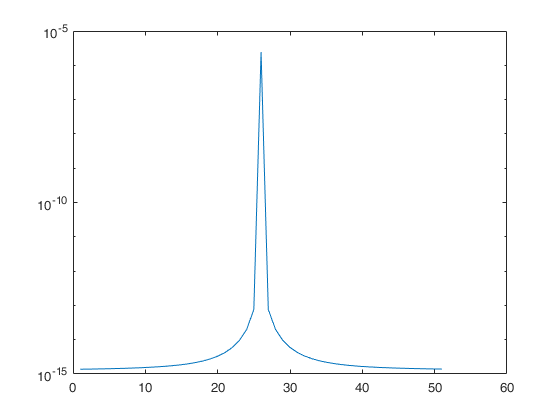

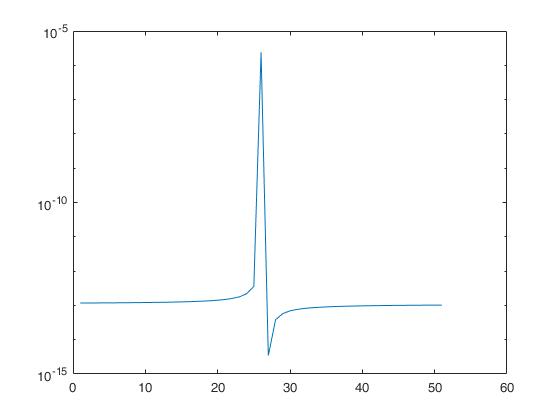

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));


max_enhancement = 1.7543e+09;%0;
min_enhancement = 3.1858e+04;%1e12;

%for job = ["cylinder_dimer_no_substrate_111_5" "cylinder_dimer_no_substrate_111_4"...
%        "cylinder_dimer_no_substrate_111_3" "cylinder_dimer_no_substrate_111_2"]
for job = "cylinder_dimer_no_substrate_111_3"
    
fft_enhancement = [];

    eval(job);
    extra_options = matthew_extra_options(options);
    load([options.output_dir_final 'sweep_data.mat']);
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        sum_fft = sweep_data(study_num,:).SumFFT{1};
        
        denom = derived_values.parameters.I0*derived_values.parameters.I0_i;
            
        wlengths = 299792458./derived_values.signal.freq;
        
        for cut_plane_index = 1:length(extra_options.cut_plane)
            for direction = extra_options.direction
                
                [FTx, FTy, FTz,FThx, FThy, FThz, FTpoynting] = ...
                    matthew_get_fft_of_cut_plane_all_freqs(sum_fft, ...
                    extra_options.cut_plane(cut_plane_index), direction);
                
                for FT_num = 5%1:5
                    switch FT_num
                        case 1
                            FTxyz = FTx;
                            FThxyz = FThx;
                        case 2
                            FTxyz = FTy;
                            FThxyz = FThy;
                        case 3
                            FTxyz = FTz;
                            FThxyz = FThz;
                        case 4
                            FTxyz = abs(FTx).^2 + abs(FTy).^2;
                            FThxyz = abs(FThx).^2 + abs(FThy).^2;
                        otherwise
                            FTxyz = FTpoynting;
                    end
                        
                    % {
                    fprintf(strcat("phi = ", sweep_data(study_num,:).phi,...
                        ", orientation_xy = ", sweep_data(study_num,:).orientation_xy));
                    %}
                    %{
                    fprintf(strcat("theta = ", sweep_data(study_num,:).theta));
                    fft_enhancement = [fft_enhancement, max(abs(FTxyz(:,2,2)))/abs(FTxyz(1,2,2))];
                    %}
                    %{
                    if fft_enhancement(end) > max_enhancement
                        max_enhancement = fft_enhancement(end);
                    end
                    if fft_enhancement(end) < min_enhancement
                        min_enhancement = fft_enhancement(end);
                    end
                    %}
                    
                    [X,Y] = meshgrid(...
                        -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                                2/pi-4/(pi*(length(FTxyz)-1)),...
                        -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                                2/pi-4/(pi*(length(FTxyz)-1)));
                            
                    
                    fig = figure;
                    semilogy(wlengths, (abs(FTxyz(:,2,2)))/denom);
                    set(gca, 'FontSize', 12);
                    %fprintf("times enhancement = %g\n", fft_enhancement(end));
                    ylabel('abs(Farfield Poynting)/(I_0\times I_{0,idler}) [W/m^2]^{-1}', 'FontSize', 16);
                    xlabel('Wavelength (nm)', 'FontSize', 16);
                    
                    hold on;
                    all_orders = abs(FTxyz(:,1,1)) + abs(FTxyz(:,1,2)) + abs(FTxyz(:,1,3)) + ...
                        abs(FTxyz(:,2,1)) + abs(FTxyz(:,2,2)) + abs(FTxyz(:,2,3)) + ...
                        abs(FTxyz(:,3,1)) + abs(FTxyz(:,3,2)) + abs(FTxyz(:,3,3));
                    semilogy(wlengths, all_orders/denom);
                    leg = legend({'Zeroth Order', 'All Orders'}, 'FontSize', 12);
                    %title({job, "", ""}, 'Interpreter', 'none');
                    % {
                    title({job ;strcat("phi = ", sweep_data(study_num,:).phi,...
                        ", orientation_xy = ", sweep_data(study_num,:).orientation_xy);"";""},...
                        'Interpreter', 'none');
                    %}
                    %{
                    title({job ;strcat("phi = ", sweep_data(study_num,:).phi,...
                        ", orientation_xy = ", sweep_data(study_num,:).orientation_xy);...
                        strcat("phi_pol = ", sweep_data(study_num,:).phi_pol,...
                        ", phi_pol_i = ", sweep_data(study_num,:).phi_pol_i);"";""},...
                        'Interpreter', 'none');
                    %}
                    %figure;
                    study_num
                    %semilogy(wlengths, sweep_data.DerivedValues{study_num,1}.signal.max_Is);
                    %axis tight;
                    %axis([1548.84 1548.855 1e-16 1e-4]);
                    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_fft"), 'png');
                    
                    % {
                    figure;
                    semilogy((abs(FTxyz(:,2,2)))/denom);
                    %}
                end
            end
        end
    end
    %{
    enhancement_plot_data = [fft_enhancement(3) fft_enhancement(1) fft_enhancement(2);...
        fft_enhancement(6) fft_enhancement(4) fft_enhancement(5);...
        fft_enhancement(9) fft_enhancement(7) fft_enhancement(8)];
    imagesc([0 45 90], [0 45 90], enhancement_plot_data);
    ylabel("\phi (deg)");
    xlabel("x-y crystal orientation (deg)");
    view(0,-90);
    cb = colorbar;
    caxis([min_enhancement max_enhancement]);
    ylabel(cb, "Times enhancement at BIC")
    set(gca,'ColorScale','log');
    set(gca, 'Xtick', [0 45 90]);
    set(gca, 'Ytick', [0 45 90]);
    %title(job, 'Interpreter', 'none');
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_fft_all"), 'png');
    %}
end